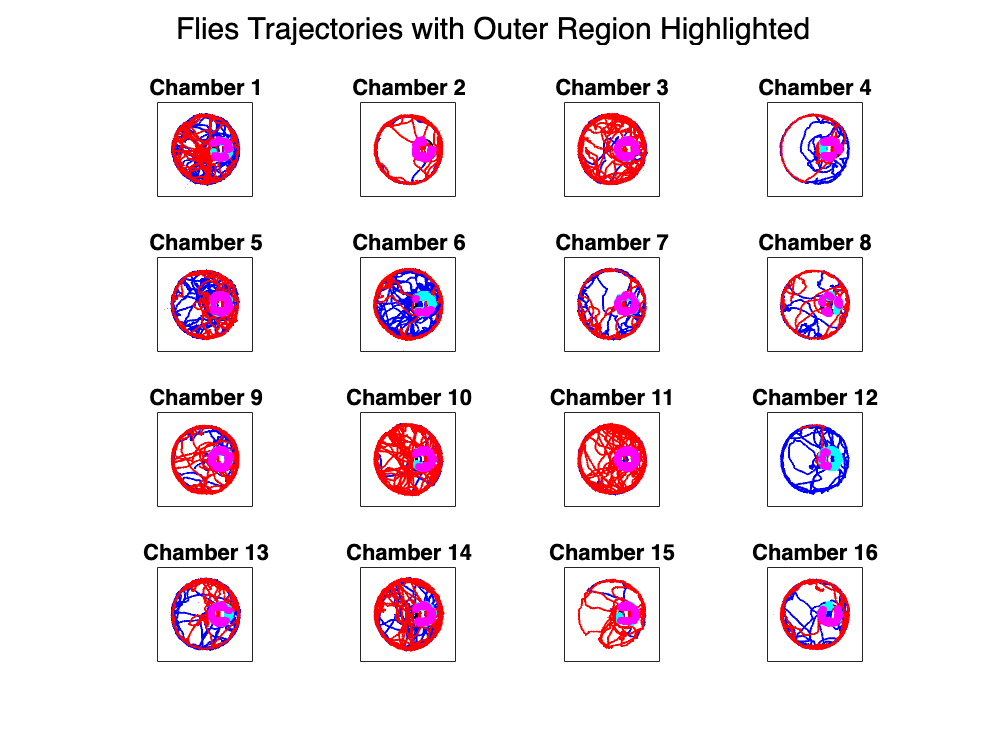

% IDs of flies (two flies per chamber)
individuals_IDs = 1:32;  % 32 flies, 16 chambers (two flies per chamber)

% Define the ROI bounds (inside the tunnel)
roi_x_min = min(14.01, 5.06);
roi_x_max = max(14.01, 5.06);
roi_y_min = min(-3.76, 4.37);
roi_y_max = max(-3.76, 4.37);

% Define the circular region (around the tunnel)
x_center = (roi_x_min + roi_x_max) / 2;
y_center = (roi_y_min + roi_y_max) / 2;
outer_radius = 6;  % Adjust the radius as needed
% Number of chambers (pairs of flies)
num_chambers = length(individuals_IDs) / 2;
% Initialize variables to store time spent around the tunnel
time_around_tunnel = zeros(2, num_chambers);

% Plot the trajectories for each pair with ROI and outer region marked
figure;
for i = 1:num_chambers
    % Get the IDs for the pair of flies in the current chamber
    fly1_id = individuals_IDs(2*i - 1);
    fly2_id = individuals_IDs(2*i);

    % Create a subplot for the current chamber
    subplot(4, 4, i);

    % Fly 1: Access its x_mm and y_mm positions
    posx1 = trxall(fly1_id).x_mm;
    posy1 = trxall(fly1_id).y_mm;

    % Fly 2: Access its x_mm and y_mm positions
    posx2 = trxall(fly2_id).x_mm;
    posy2 = trxall(fly2_id).y_mm;

    % Plot the trajectory for Fly 1
    plot(posx1, posy1, 'b-', 'LineWidth', 1);  % Blue for Fly 1
    hold on;

    % Plot the trajectory for Fly 2
    plot(posx2, posy2, 'r-', 'LineWidth', 1);  % Red for Fly 2

    % Plot the tunnel ROI
    rectangle('Position', [roi_x_min, roi_y_min, roi_x_max - roi_x_min, roi_y_max - roi_y_min], ...
              'EdgeColor', 'k', 'LineWidth', 1.5, 'LineStyle', '--');

    % Plot the outer circular region
    theta = linspace(0, 2*pi, 100);
    circle_x = x_center + outer_radius * cos(theta);
    circle_y = y_center + outer_radius * sin(theta);
    plot(circle_x, circle_y, 'k--', 'LineWidth', 1);

    % Highlight trajectory points in the outer region for Fly 1
    in_outer1 = (sqrt((posx1 - x_center).^2 + (posy1 - y_center).^2) <= outer_radius) & ...
                ~((posx1 >= roi_x_min & posx1 <= roi_x_max) & (posy1 >= roi_y_min & posy1 <= roi_y_max));
    plot(posx1(in_outer1), posy1(in_outer1), 'co', 'MarkerSize', 3, 'MarkerFaceColor', 'c');  % Cyan points

    % Highlight trajectory points in the outer region for Fly 2
    in_outer2 = (sqrt((posx2 - x_center).^2 + (posy2 - y_center).^2) <= outer_radius) & ...
                ~((posx2 >= roi_x_min & posx2 <= roi_x_max) & (posy2 >= roi_y_min & posy2 <= roi_y_max));
    plot(posx2(in_outer2), posy2(in_outer2), 'mo', 'MarkerSize', 3, 'MarkerFaceColor', 'm');  % Magenta points

    % Calculate the time spent in the outer region for Fly 1
    timestamps1 = trxall(fly1_id).timestamps;
    if sum(in_outer1) > 1
        time_around_tunnel(1, i) = sum(diff(timestamps1(in_outer1)));
    else
        time_around_tunnel(1, i) = 0;
    end

    % Calculate the time spent in the outer region for Fly 2
    timestamps2 = trxall(fly2_id).timestamps;
    if sum(in_outer2) > 1
        time_around_tunnel(2, i) = sum(diff(timestamps2(in_outer2)));
    else
        time_around_tunnel(2, i) = 0;
    end

    % Title for each subplot
    title(['Chamber ', num2str(i)]);
    axis equal;
    xlim([-30, 30]);
    ylim([-30, 30]);

    % Remove x and y tick labels
    xticks([]);
    yticks([]);
    hold off;
end
sgtitle('Flies Trajectories with Outer Region Highlighted');

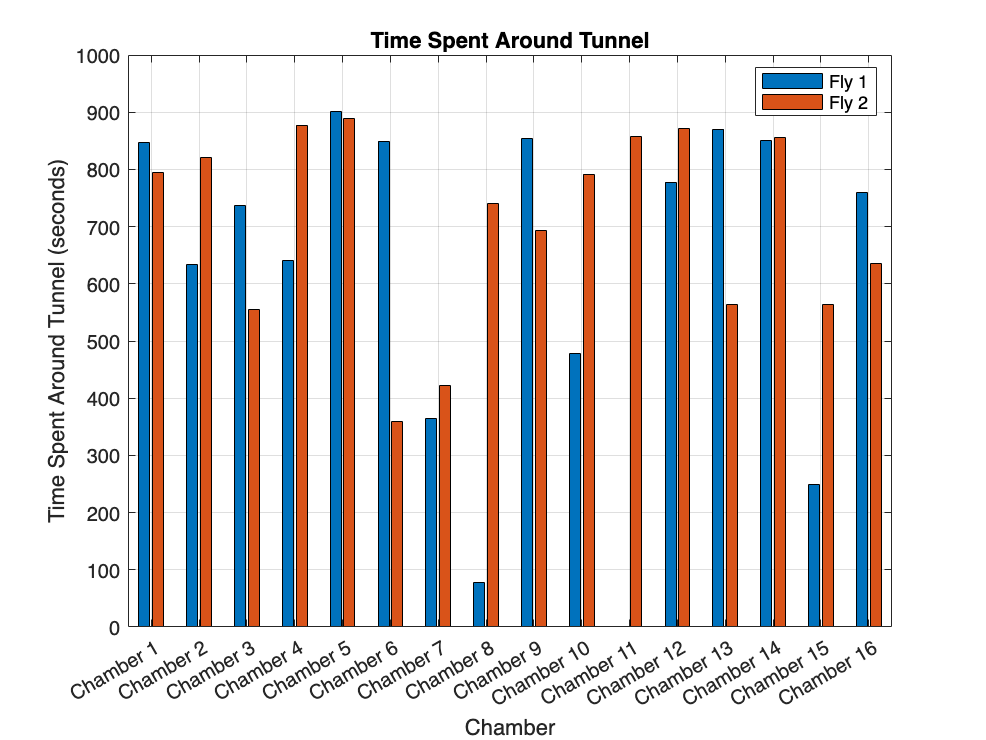


% Plot histogram of time spent in the outer region
figure ;
bar(time_around_tunnel', 'grouped');
xticks(1:num_chambers);
xticklabels(arrayfun(@(x) ['Chamber ', num2str(x)], 1:num_chambers, 'UniformOutput', false));
xlabel('Chamber');
ylabel('Time Spent Around Tunnel (seconds)');
legend({'Fly 1', 'Fly 2'}, 'Location', 'best');
title('Time Spent Around Tunnel');
grid on;

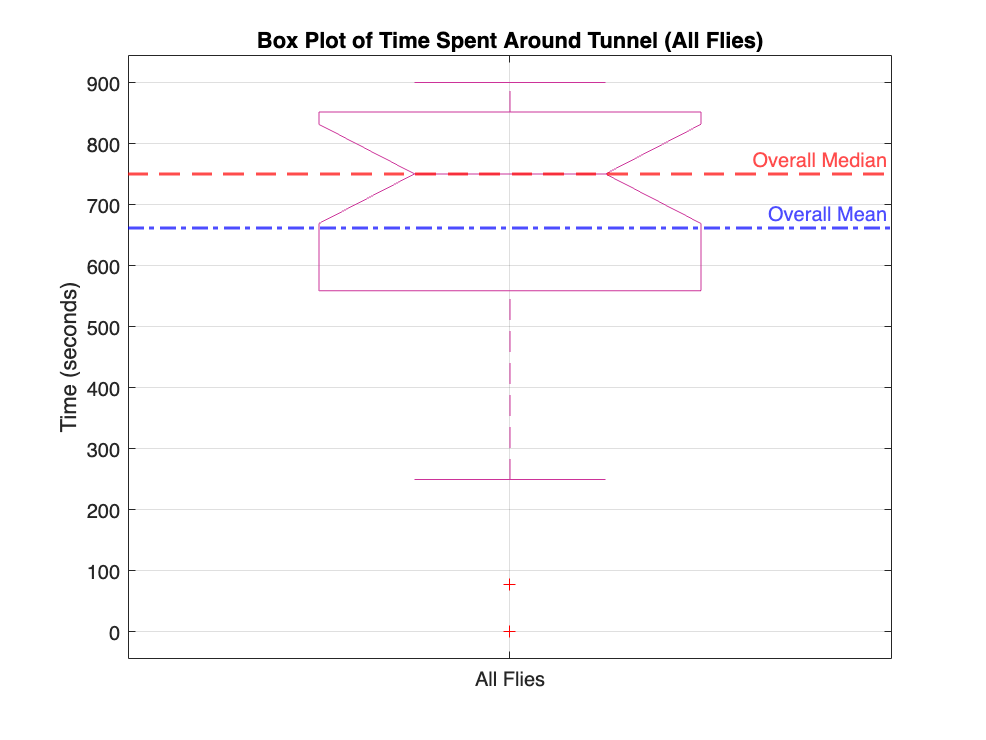


% Combine time spent in the outer region across all flies
all_time_around_tunnel = time_around_tunnel(:);

% Create a box plot for time spent in the outer region
figure;
boxplot(all_time_around_tunnel, 'Notch', 'on', 'Colors', [0.8, 0.2, 0.6], 'Widths', 0.5);
hold on;
median_time = median(all_time_around_tunnel);
mean_time = mean(all_time_around_tunnel);
yline(median_time, '--r', 'LineWidth', 1.5, 'Label', 'Overall Median');
yline(mean_time, '-.b', 'LineWidth', 1.5, 'Label', 'Overall Mean');
xticks(1);
xticklabels({'All Flies'});
ylabel('Time (seconds)');
title('Box Plot of Time Spent Around Tunnel (All Flies)');
grid on;
hold off;

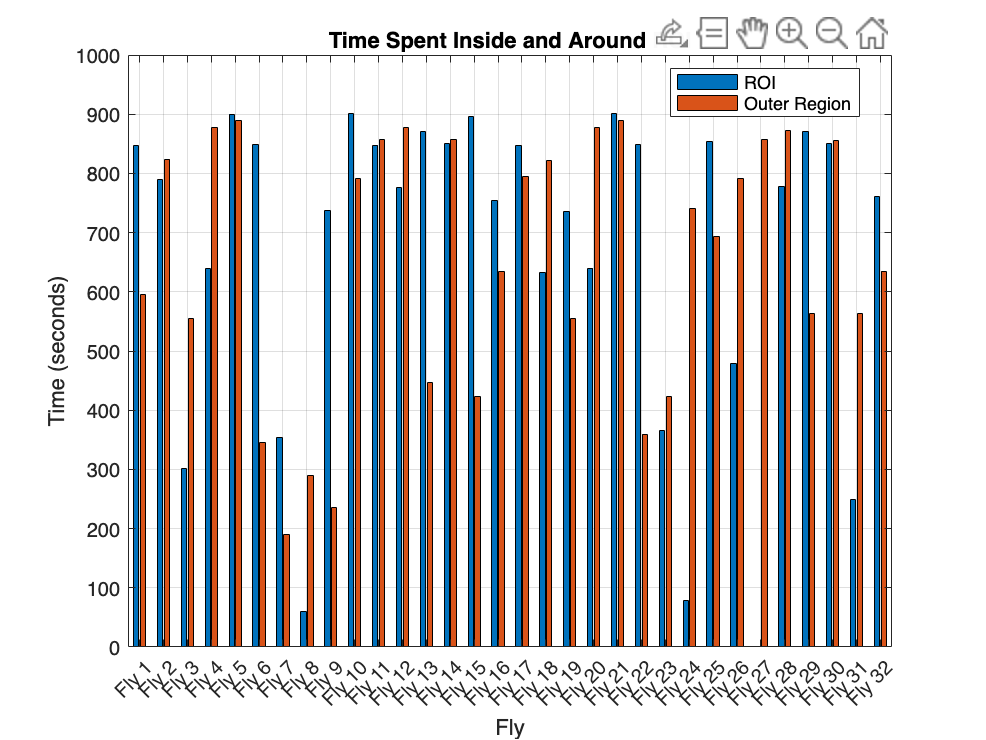


% Initialize variables to store time spent in ROI and outer region
time_in_roi = zeros(2, num_chambers);         % Rows: fly 1 & fly 2, Columns: chambers
time_in_outer = zeros(2, num_chambers);      % Rows: fly 1 & fly 2, Columns: chambers

for i = 1:num_chambers
    % Get the IDs for the pair of flies in the current chamber
    fly1_id = individuals_IDs(2*i - 1);
    fly2_id = individuals_IDs(2*i);

    % Fly 1: Access positions and timestamps
    posx1 = trxall(fly1_id).x_mm;
    posy1 = trxall(fly1_id).y_mm;
    timestamps1 = trxall(fly1_id).timestamps;

    % Fly 2: Access positions and timestamps
    posx2 = trxall(fly2_id).x_mm;
    posy2 = trxall(fly2_id).y_mm;
    timestamps2 = trxall(fly2_id).timestamps;

    % Fly 1: Inside ROI
    in_roi1 = (posx1 >= roi_x_min & posx1 <= roi_x_max) & (posy1 >= roi_y_min & posy1 <= roi_y_max);
    if sum(in_roi1) > 1
        time_in_roi(1, i) = sum(diff(timestamps1(in_roi1)));  % Time in ROI
    end

    % Fly 1: In outer circular region but not inside ROI
    in_outer1 = (sqrt((posx1 - x_center).^2 + (posy1 - y_center).^2) <= outer_radius) & ...
                ~((posx1 >= roi_x_min & posx1 <= roi_x_max) & (posy1 >= roi_y_min & posy1 <= roi_y_max));
    if sum(in_outer1) > 1
        time_in_outer(1, i) = sum(diff(timestamps1(in_outer1)));  % Time in outer region
    end

    % Fly 2: Inside ROI
    in_roi2 = (posx2 >= roi_x_min & posx2 <= roi_x_max) & (posy2 >= roi_y_min & posy2 <= roi_y_max);
    if sum(in_roi2) > 1
        time_in_roi(2, i) = sum(diff(timestamps2(in_roi2)));  % Time in ROI
    end

    % Fly 2: In outer circular region but not inside ROI
    in_outer2 = (sqrt((posx2 - x_center).^2 + (posy2 - y_center).^2) <= outer_radius) & ...
                ~((posx2 >= roi_x_min & posx2 <= roi_x_max) & (posy2 >= roi_y_min & posy2 <= roi_y_max));
    if sum(in_outer2) > 1
        time_in_outer(2, i) = sum(diff(timestamps2(in_outer2)));  % Time in outer region
    end
end

% Combine times into one array for bar plot
time_comparison = cat(3, time_in_roi, time_in_outer);

% Plot the time spent in ROI and outer region for each fly
figure;
bar(reshape(permute(time_comparison, [2, 3, 1]), [], 2), 'grouped');
xticks(1:2*num_chambers);
xticklabels(arrayfun(@(x) ['Fly ', num2str(x)], 1:2*num_chambers, 'UniformOutput', false));
xlabel('Fly');
ylabel('Time (seconds)');
legend({'ROI', 'Outer Region'}, 'Location', 'best');
title('Time Spent Inside and Around ROI');
grid on;

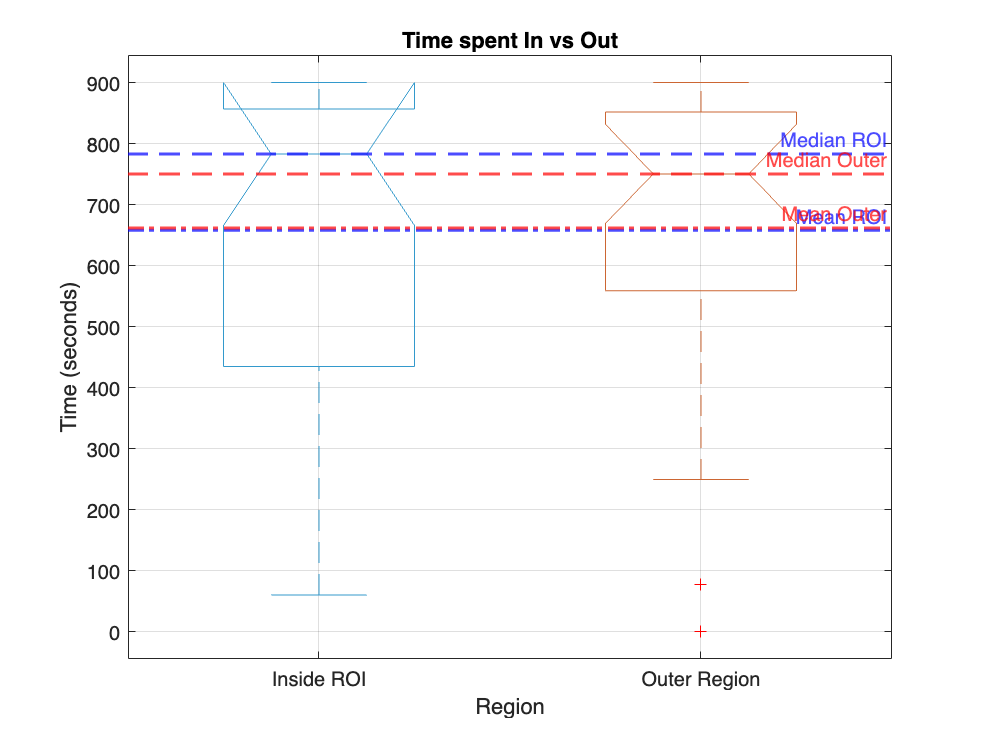


% Combine time across all flies for box plot
all_time_in_roi = time_in_roi(:);  % Flatten array
all_time_in_outer = time_in_outer(:);

% Create box plot
figure;
boxplot([all_time_in_roi, all_time_in_outer], ...
        'Labels', {'Inside ROI', 'Outer Region'}, ...
        'Notch', 'on', 'Colors', [0.2 0.6 0.8; 0.8 0.4 0.2], ...
        'Widths', 0.5);
hold on;

% Overlay lines for mean and median
median_roi = median(all_time_in_roi);
median_outer = median(all_time_in_outer);
mean_roi = mean(all_time_in_roi);
mean_outer = mean(all_time_in_outer);

yline(median_roi, '--b', 'Median ROI', 'LineWidth', 1.5);
yline(mean_roi, '-.b', 'Mean ROI', 'LineWidth', 1.5);
yline(median_outer, '--r', 'Median Outer', 'LineWidth', 1.5);
yline(mean_outer, '-.r', 'Mean Outer', 'LineWidth', 1.5);

xlabel('Region');
ylabel('Time (seconds)');
title('Time spent In vs Out');
grid on;
hold off;